# Stereo Decomposition

A decomposition of a stereo signal into direct and ambient components will be implemented following the methods described in Multiple Loudspeaker Playback of Stereo Signals by Christof Faller JAES, 54(11), 2006. 

## Read in Stereo Signal

clear all
% Read in a stereo signal
[sig,fs] = audioread('samplemusic.wav') ;
sigLen = size(sig,1) ;

## Cochlear Mask Function

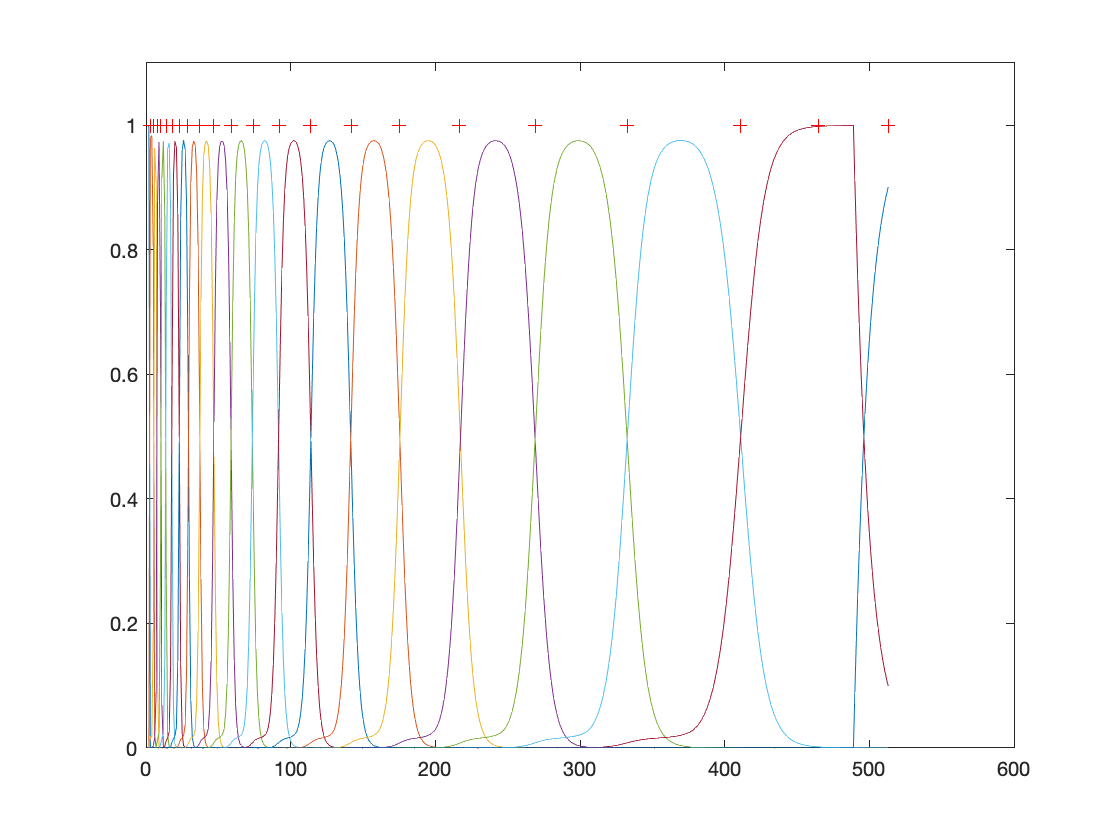

% Set parameters
quickProcessing = 1 ;
if ~quickProcessing
    % Set for Better Results
    nFreqBins = 4096 ;
    sFreq = fs ;
    nChan = 64 ;
    loFreq = 50 ;
    hiFreq = 20000 ;
    spl = 70 ;
else
    % Set for Quicker Processing
    nFreqBins = 1024 ;
    sFreq = fs ;
    nChan = 20 ;
    loFreq = 150 ;
    hiFreq = 20000 ;
    spl = 70 ;
end

[cochlearWeights, cochlearFreq, cochlearBandIdx, cochlearBinWidth] = ...
    CochlearMask(nFreqBins, sFreq, nChan, loFreq, hiFreq, spl) ;

figure
plot(cochlearWeights.') ;
hold on
plot(cochlearBandIdx,ones(size(cochlearBandIdx)),'r+') ;
ylim([0 1.1])

% Transpose cochlear weights
cochlearWeights = cochlearWeights.' ;

## Set up for Time-Frequency Processing

% Setup Overlap-Add Parameters
numHops = 2 ;
hopSize =  1024 / numHops ;
winLen = hopSize*numHops ; % usually around 20 ms
zeroPad = (nFreqBins - winLen)/2 ;
frameLen = winLen + 2*zeroPad ;
% Use this winFun if numHops > 2
%winFun = hann(winLen,'periodic') / sqrt(numHops * (3/8)) ;
% Use this winFun if numHops = 2
winFun = sqrt(hann(winLen,'periodic')) ; %50 percent overlap and add
dHopTime = hopSize / fs;

% Initialization for Overlap Add Processing
sig = [zeros(winLen, 2); sig; zeros(winLen-mod(sigLen,hopSize), 2)] ;
pIn  = 0; pEnd = length(sig) - winLen ;
outSigDirect = zeros(pEnd+frameLen, 2) ;
outSigAmbient = zeros(pEnd+frameLen, 2) ;
outSig = zeros(pEnd+frameLen, 2) ;
freqAxis = [0:frameLen-1].' * fs / frameLen ;
freqAxis = freqAxis(1:frameLen/2+1) ;

% Custom Initialization
% Time constants for coherence
tau_ICC = 50; % 50 ms
% ICLD Range
ICLDRange = 30 ;
% Forgeting/Remembering factor for coherence
alpha   = 1/(tau_ICC*fs/1000/hopSize);
numCochlearBands = length(cochlearBandIdx) ;
sigPxx = ones(nFreqBins/2 + 1, 2) * 1e-10 ;
sigPxy = ones(nFreqBins/2 + 1, 1) * 1e-10 ;

## Process Audio Using Overlap-Add Processing

progBar = TextProgressBar(0) ;

   [__________________________________________________]   0%

index = 0 ;
while pIn < pEnd
    
    index = index + 1 ;
    prog = pIn/pEnd ;
    progBar = TextProgressBar(prog, progBar) ;
    
    dTime = index * dHopTime;
    
    % convert to frequency domain
    frameSpecSig(:, 1) = ComputeFrame(sig(pIn+1:pIn+winLen,1), ...
        winFun.^2, zeroPad) ;
    frameSpecSig(:, 2) = ComputeFrame(sig(pIn+1:pIn+winLen,2), ...
        winFun.^2, zeroPad) ;
    
    % create amplitude weighted cochlear spectral signal
    cochlearSpecSig1 = frameSpecSig(:, 1) .* cochlearWeights ;
    cochlearSpecSig2 = frameSpecSig(:, 2) .* cochlearWeights ;
    
    % calculate the power in each cochlear band
    % use orginal spectrum and the band indices
    startIdx = 1 ;
    for I = 1 : numCochlearBands
        endIdx = cochlearBandIdx(I) ;
        cochlearPxx(I,1) = sum(abs(frameSpecSig(startIdx:endIdx, 1)).^2) / cochlearBinWidth(I) ;
        cochlearPxx(I,2) = sum(abs(frameSpecSig(startIdx:endIdx, 2)).^2) / cochlearBinWidth(I) ;
        startIdx = endIdx + 1 ;
    end
    origCochlearPxx = cochlearPxx ;
    
    % calculate the Inter-channel Level Difference for each cochlear band
    cochlearICLD = 10.*log10((cochlearPxx(:, 2) + 1e-40) ./ (cochlearPxx(:, 1) + 1e-40));
    
    % limit the ICLD to +- ICLDRange dB
    cochlearICLD(find(cochlearICLD > ICLDRange)) = ICLDRange ;
    cochlearICLD(find(cochlearICLD < -ICLDRange)) = -ICLDRange ;
    % Reformulate the cochlear power with the ICLD limit
    cochlearPxx(:, 1) = ones( size(cochlearPxx(:,1)) ) ;
    cochlearPxx(:, 2) = cochlearPxx(:, 1).*10.^(cochlearICLD/10) ;
    
    % calculate coherence for each FFT bin
    % signal power with forgetting
    sigPxx(:, 1) = alpha * abs(frameSpecSig(:, 1)).^2 + (1-alpha) * sigPxx(:, 1) ;
    sigPxx(:, 2) = alpha * abs(frameSpecSig(:, 2)).^2 + (1-alpha) * sigPxx(:, 2) ;
    % calculate the signal cross-correlation with forgetting
    sigPxy = alpha * frameSpecSig(:, 1) .* conj( frameSpecSig(:, 2) ) + ...
        (1-alpha) * sigPxy ;
    
    % normalise the cross-correltion
    sigCohSpec = abs(sigPxy+1e-10)./sqrt(sigPxx(:, 1).*sigPxx(:, 2)+1e-20);
    
    % calculate the signal power spectrum
    sigPowSpec = abs(frameSpecSig(:,1)).^2 + abs(frameSpecSig(:,2)).^2;
    
    % calculate Cochlear band coherence
    % use the band indices
    % use the signal power spectrum for normalised weighting
    startIdx = 1 ;
    for I = 1 : numCochlearBands
        endIdx = cochlearBandIdx(I) ;
        cochlearCoh(I,1) = sum(sigPowSpec(startIdx:endIdx) .* sigCohSpec(startIdx:endIdx)) / ...
            sum(sigPowSpec(startIdx:endIdx)+1e-20);
        startIdx = endIdx + 1 ;
    end

    % Keep cochlear coherence in range
    cochlearCoh = max(cochlearCoh, 0) ;
    cochlearCoh = min(cochlearCoh, 1) ;
    cochlearCoh(find(cochlearCoh == 1)) = 0.99 ;
    cochlearCoh(find(cochlearCoh == 0)) = 0.01 ;
    
    % calculate cochlearPS, cochlearA, cochlearPN
    cochlearC = cochlearCoh .* sqrt( cochlearPxx(:,1) .* cochlearPxx(:,2) ) ;
    cochlearB = cochlearPxx(:,2) - cochlearPxx(:,1) + ...
                sqrt( (cochlearPxx(:,1) - cochlearPxx(:,2)).^2 + 4 * cochlearC.^2 ) ;
    cochlearPS = 2 * cochlearC.^2 ./ cochlearB ;
    cochlearA = cochlearB ./ (2*cochlearC) ;
    cochlearPN = cochlearPxx(:,1) - cochlearPS ;
    
    % calculate linear prediction weights
    cochlearDenom = (cochlearA.^2 + 1) .* cochlearPS .* cochlearPN + cochlearPN.^2 ;
    cochlearW1 = (cochlearPS .* cochlearPN) ./ cochlearDenom ;
    cochlearW2 = cochlearA .* cochlearW1 ;
    cochlearW3 = (cochlearA.^2 .* cochlearPS .* cochlearPN + cochlearPN.^2) ./ ...
                 cochlearDenom ;
    cochlearW4 = (-cochlearA .* cochlearPS .* cochlearPN) ./ cochlearDenom ;
    cochlearW5 = cochlearW4 ;
    cochlearW6 = (cochlearPS .* cochlearPN + cochlearPN.^2) ./ cochlearDenom ;
    
    % calculate Postscaling Factors
    cochlearScalePS = cochlearPS ./ ( (cochlearW1 + cochlearA.*cochlearW2).^2 .* cochlearPS + ...
                                             (cochlearW1.^2 + cochlearW2.^2) .* cochlearPN ) ;
    cochlearScaleN1 = sqrt( cochlearPN ./ ( (cochlearW3 + cochlearA.*cochlearW4).^2 .* cochlearPS + ...
                                             (cochlearW3.^2 + cochlearW4.^2) .* cochlearPN ) ) ;
    cochlearScaleN2 = sqrt( cochlearPN ./ ( (cochlearW5 + cochlearA.*cochlearW6).^2 .* cochlearPS + ...
                                             (cochlearW5.^2 + cochlearW6.^2) .* cochlearPN ) ) ;                                   
    
    % calculate specS1, specS2, specN1, specN2  
    specS1 = zeros( size(frameSpecSig(:,1)) ) ;
    specS2 = zeros( size(frameSpecSig(:,1)) ) ;
    specN1 = zeros( size(frameSpecSig(:,1)) ) ;
    specN2 = zeros( size(frameSpecSig(:,1)) ) ;
    for I = 1 : numCochlearBands
        specS1 = specS1 +  (1/sqrt(1 + cochlearA(I)^2)) * cochlearScalePS(I) * ...
            ( cochlearW1(I) * cochlearSpecSig1(:, I) + cochlearW2(I) * cochlearSpecSig2(:, I) ) ;  
        specS2 = specS2 +  (cochlearA(I)/sqrt(1 + cochlearA(I)^2)) * ( cochlearA(I) * cochlearScalePS(I) ) * ...
             ( cochlearW1(I) * cochlearSpecSig1(:, I) + cochlearW2(I) * cochlearSpecSig2(:, I) ) ;
        specN1 = specN1 + cochlearScaleN1(I) * ...
            ( cochlearW3(I) * cochlearSpecSig1(:, I) + cochlearW4(I) * cochlearSpecSig2(:, I) ) ; 
        specN2 = specN2 + cochlearScaleN2(I) * ...
            ( cochlearW5(I) * cochlearSpecSig1(:, I) + cochlearW6(I) * cochlearSpecSig2(:, I) ) ;  
    end
    
    % save data for plotting
    mem_cochlearPxx1(:,index) = origCochlearPxx(:,1) ;
    mem_cochlearPxx2(:, index) = origCochlearPxx(:,2) ;
    mem_cochlearICLD(:, index) = cochlearICLD ;
    mem_cochlearICC(:, index) = cochlearCoh ;
    
    
    applyWin = 0 ;
    winFunOut = winFun ;
    outSig(pIn+1:pIn+frameLen,1) = ...
        ReconstructFrame(outSig(pIn+1:pIn+frameLen,1), frameSpecSig(:,1), ...
        winFunOut, applyWin);
    outSig(pIn+1:pIn+frameLen,2) = ...
        ReconstructFrame(outSig(pIn+1:pIn+frameLen,2), frameSpecSig(:,2), ...
        winFunOut, applyWin);
    
    outSigDirect(pIn+1:pIn+frameLen,1) = ...
        ReconstructFrame(outSigDirect(pIn+1:pIn+frameLen,1), specS1, ...
        winFunOut, applyWin);
    outSigDirect(pIn+1:pIn+frameLen,2) = ...
        ReconstructFrame(outSigDirect(pIn+1:pIn+frameLen,2), specS2, ...
        winFunOut, applyWin);
    
    outSigAmbient(pIn+1:pIn+frameLen,1) = ...
        ReconstructFrame(outSigAmbient(pIn+1:pIn+frameLen,1), specN1, ...
        winFunOut, applyWin);
    outSigAmbient(pIn+1:pIn+frameLen,2) = ...
        ReconstructFrame(outSigAmbient(pIn+1:pIn+frameLen,2), specN2, ...
        winFunOut, applyWin);    
    
    
    pIn = pIn + hopSize ;

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%] 100%

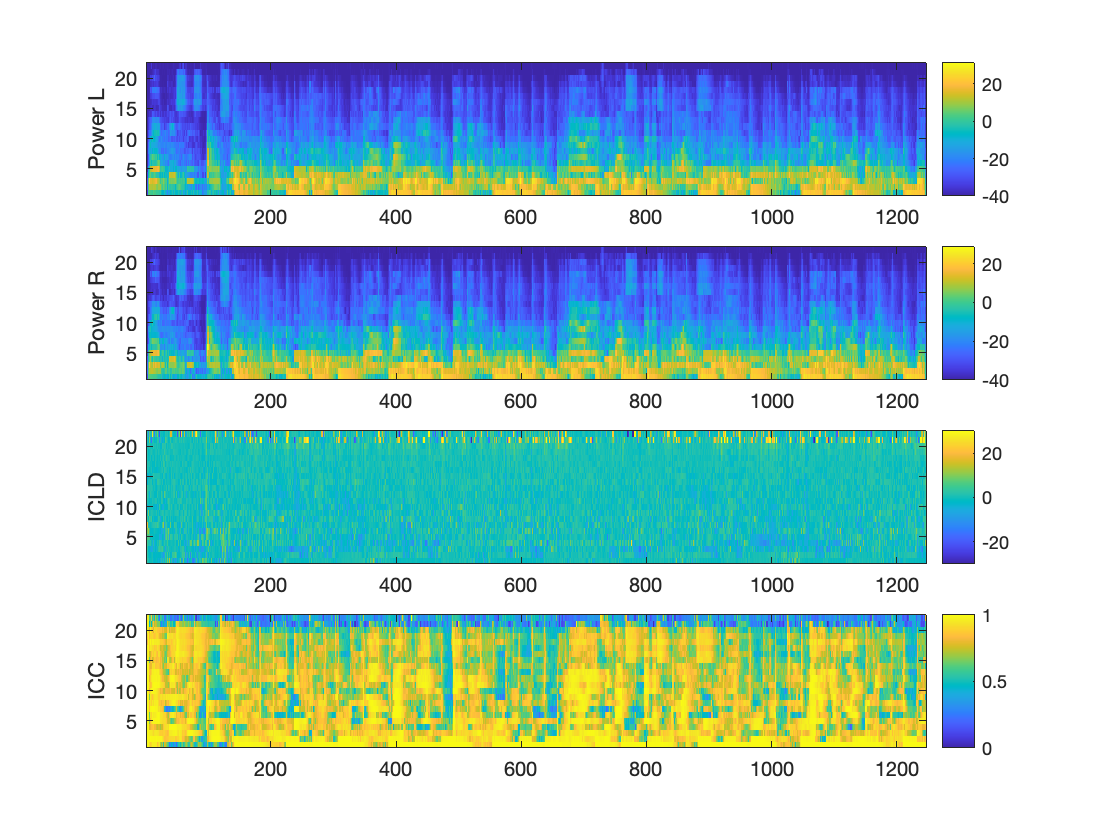


TextProgressBar('close') ;
% Restrict the output Signal to the processed signal
outSig = outSig(winLen+1+zeroPad:winLen+sigLen+zeroPad,:) ;
outSigDirect = outSigDirect(winLen+1+zeroPad:winLen+sigLen+zeroPad,:) ;
outSigAmbient = outSigAmbient(winLen+1+zeroPad:winLen+sigLen+zeroPad,:) ;

figure
subplot(4,1,1)
imagesc(10*log10(mem_cochlearPxx1+1e-4))
colorbar
ylabel('Power L')
axis xy
subplot(4,1,2)
imagesc(10*log10(mem_cochlearPxx2+1e-4))
colorbar
ylabel('Power R')
axis xy
subplot(4,1,3)
imagesc(mem_cochlearICLD, [-ICLDRange ICLDRange])
colorbar
ylabel('ICLD')
axis xy
subplot(4,1,4)
imagesc(mem_cochlearICC,[0 1])
colorbar
ylabel('ICC')
axis xy